# Near Field Communication (NFC)

This example shows you how to model communication between two Near Field Communication (NFC) devices. 

## Introduction

Near Field Communication (NFC) is a standards-based short-range wireless connectivity technology, designed for intuitive and simple communication between two electronic devices. NFC operates at 13.56 MHz center frequency (Fc), at rates ranging from 106 kbps to 424 kbps, and its typical operating range is 10 cm or less. NFC always involves an Initiator and a Target - the Initiator actively generates an electromagnetic field that can power a passive Target.

ISO®/IEC 18092 (Telecommunications and Information Exchange Between Systems - Near Field Communication - Interface and Protocol), also referred to as NFCIP-1 (Near Field Communication - Interface and Protocol Specification), is the governing international Standard for NFC. It is based on ISO/IEC 14443. ISO/IEC 18092 includes two communication modes:

- Passive: The Initiator device generates a carrier field and the Target device answers by modulating the existing field. In this mode, the Target device draws its operating power from the Initiator-provided electromagnetic field.

- Active: Both Initiator and Target device communicate by alternately generating their own fields. A device deactivates its RF field while it is waiting for data. In this mode, both devices typically have power supplies.

Within the two modes of communication there are three modes of operation defined in ISO/IEC 18092:

- Read/Write: In this mode, the NFC device can read data from or write data to any of the supported NFC tags (contactless cards) in a standard NFC data format. The applications include reading information stored in inexpensive NFC tags embedded in labels or smart posters.

- Card Emulation: The NFC device can also act as an NFC tag for other readers. This enables NFC-enabled devices like smart phones to act like smart cards to perform transactions such as payments or ticketing.

- Peer-to-Peer: Two NFC devices can exchange data. The applications include sharing a Wi-Fi® or Bluetooth® link, or exchanging data in the form of virtual business cards and photos.

## System Setup

This example illustrates the NFC protocol and commands required to transmit data from an Initiator to a Target. The passive communication mode is used here whereby the Initiator provides the electromagnetic field and the Target sends the information back by modulating this field. The Initiator is operating as a writer and the Target as card emulator or tag. The Initiator and Target use the Type A air interface defined in ISO/IEC 14443-2 (Identification cards - Contactless integrated circuit cards - Proximity cards - Part 2: Radio frequency power and signal interface) and are operating at 106 kbps. The Initiator uses Modified Miller coding with 100% ASK, as shown in the Time scope below. The Target generates a subcarrier with frequency 847.5 kHz (Fs), via load modulation, using the Initiator's field and then modulates the data onto the Initiator's carrier frequency using this subcarrier. The Spectrum Analyzer illustrates the load modulation below. To highlight the subcarrier at 847.5 kHz, select Tools->Measurements->Peak Finder in the spectrum analyzer window. The Target uses Manchester coding with 10% ASK as shown in the Time scope below. Note that the time domain signals shown in the two Time scopes are baseband signals i.e the 13.56 MHz carrier signal is stripped out.

The nfcInitiator object represents the Initiator. The UserData property holds the data to be transmitted to the Target. The nfcTarget object represents the Target and ReceivedUserData holds the data received from the Initiator. Due to short range of NFC devices, the system SNR is very high.

initiator = nfcInitiator

initiator =                      Fc: 13560000
       SamplesPerSymbol: 128
                     t1: 32
               AppLayer: []
               UserData: 'Hello, from MathWorks.'
    EnableVisualization: 1


target = nfcTarget

target =                      Fc: 13560000
                     Fs: 847500
       SamplesPerSymbol: 128
                    UID: '11aa22bb'
               AppLayer: []
       ReceivedUserData: ''
    EnableVisualization: 1


% Signal to noise ratio, in dB
snrdB = 50;
% Reset the RNG for reproducible results 
s = rng(0);

## Initialization and Anticollision

The Initiator and Target follow initialization and anticollision sequences to establish a communication link. Figure 9 (Initialization and anticollision flowchart for PCD) and Figure 10 (Anticollision loop, flowchart for PCD) in ISO/IEC 14443-3 (Identification cards - Contactless integrated circuit cards - Proximity cards, Part 3: Initialization and anticollision) illustrate the corresponding flowcharts. Section 6 (Type A - Initialization and anticollision) of ISO/IEC 14443-3 describes the commands and protocol in detail. Functions nfcInitialization() and nfcAnticollisionLoop() implement the corresponding sequence of commands and protocol. The example prints the status and actions of Initiator and Target devices, along with important information that is exchanged, to indicate the flow of commands.

## Transport Protocol

As described in ISO/IEC 18092, Transport protocol has three parts -

- Activation of protocol: Various protocol parameters, like bit rates, are negotiated and selected during this phase. Section 12.5 (Activation of the protocol) of ISO/IEC 18092 describes this phase in details. The function nfcProtocolActivation() implements the sequence of commands required during this phase.

- Data Exchange Protocol: The information is exchanged during this phase using a half-duplex protocol that supports block oriented data transmission with error handling. See section 12.6 (Data Exchange Protocol) of ISO/IEC 18092 for details. Function nfcDataExchangeProtocol() shows how to implement the exchange of data as prescribed by the ISO/IEC 18092.

- Deactivation of Protocol: After completing data exchange, the Initiator deactivates the protocol and connection with the Target. Function nfcProtocolDeactivation() implements the sequence described in section 12.7 (Deactivation of the protocol) of ISO/IEC 18092.

nfcPrint.Message('The message to transmit from Initiator to Target:');

The message to transmit from Initiator to Target:


nfcPrint.Message(initiator.UserData);

Hello, from MathWorks.



nfcPrint.Start();


Start of NFC Communication between Initiator and Target



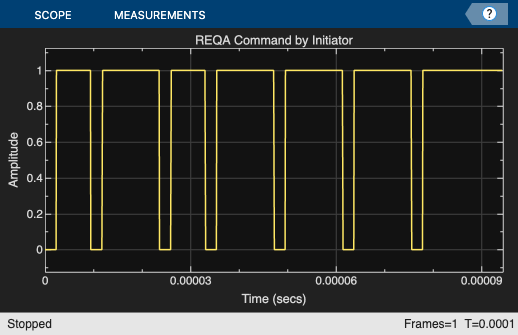

	Initiator transmitted REQA
Puterea semnalului transmis masurata: 29.16453949 dBm
Puterea semnalului receptionat masurata: 29.16488946 dBm
Puterea zgomotului receptionat masurata: -20.83546051 dBm
    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 0"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txREQA: 1"    "txR

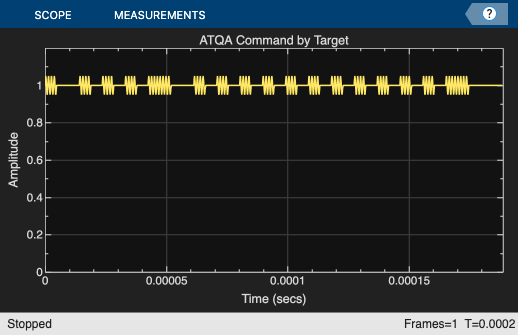

		Target transmitted ATQA in response to REQA


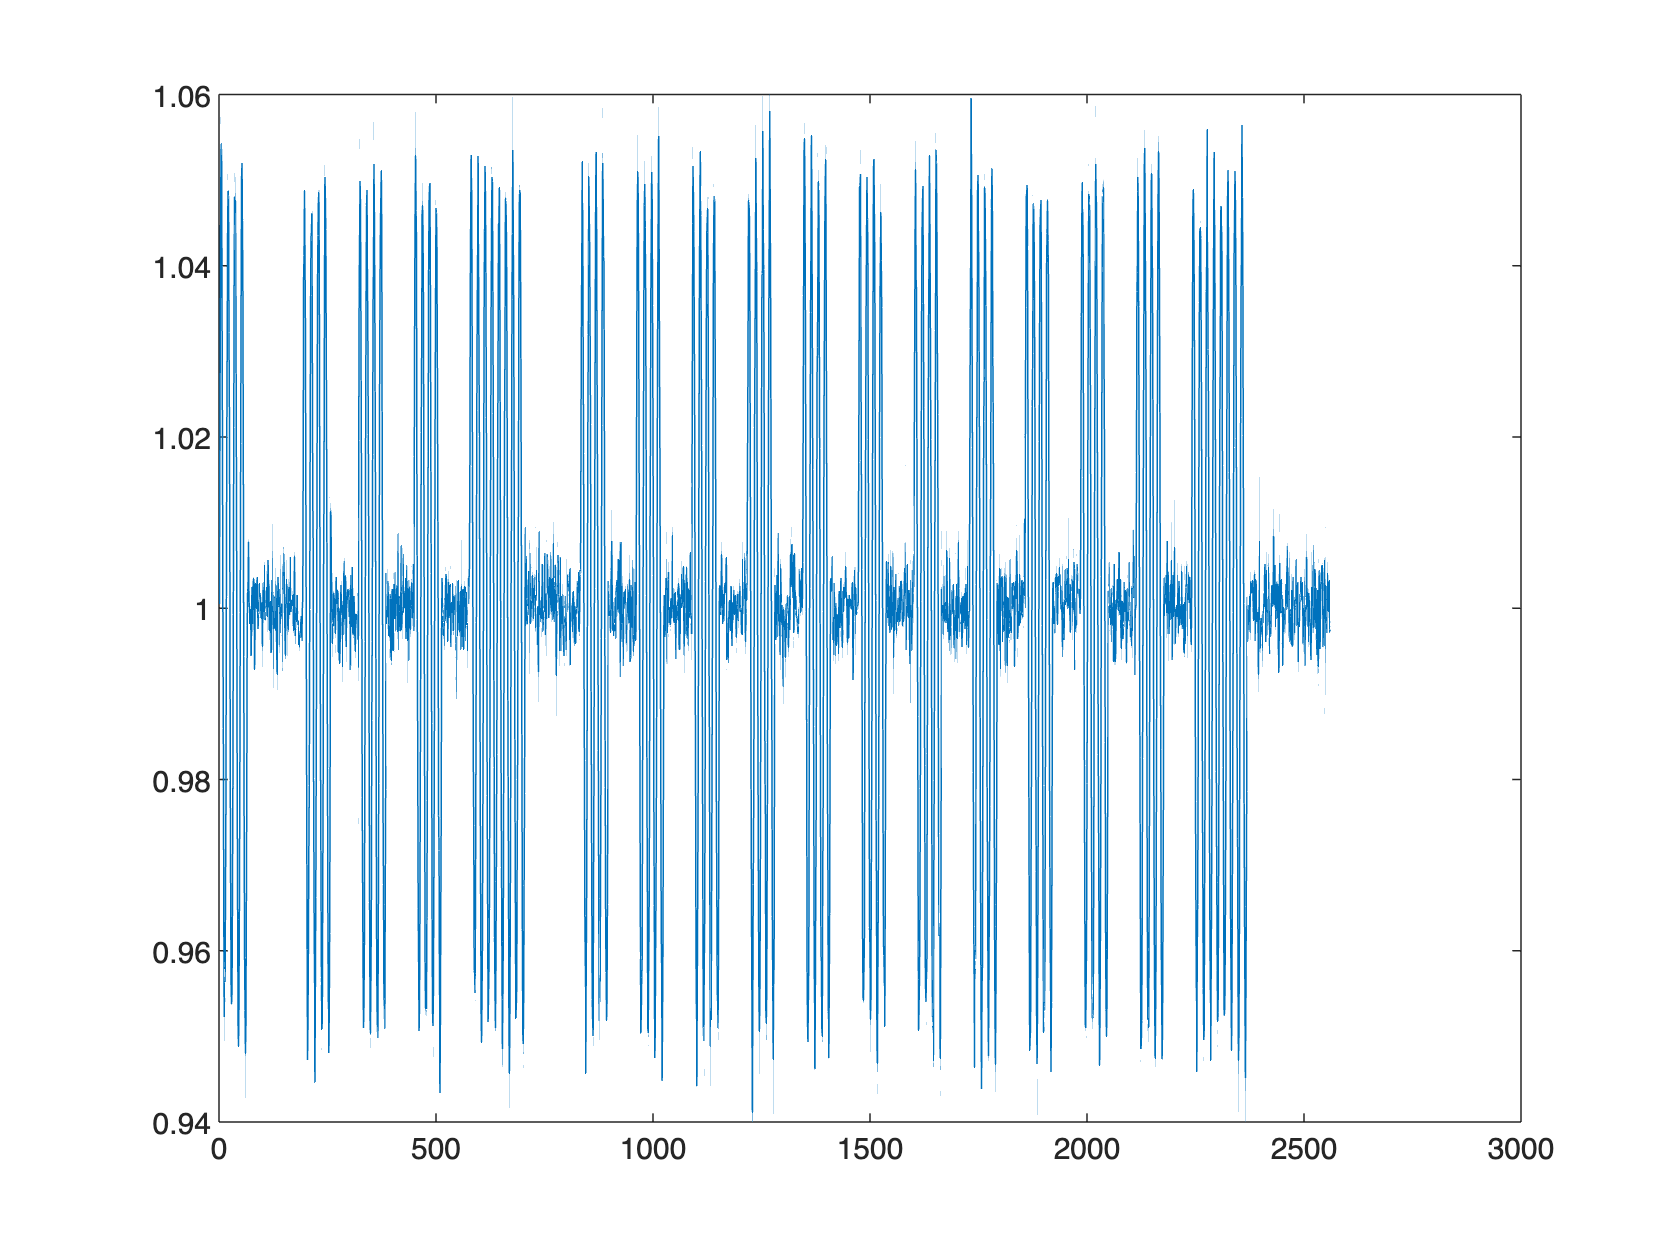

  Columns 1 through 1902

    "txATQA: 1"    "txATQA: 1.0191"    "txATQA: 1.0354"    "txATQA: 1.0462"    "txATQA: 1.05"    "txATQA: 1.0462"    "txATQA: 1.0354"    "txATQA: 1.0191"    "txATQA: 1"    "txATQA: 0.98087"    "txATQA: 0.96464"    "txATQA: 0.95381"    "txATQA: 0.95"    "txATQA: 0.95381"    "txATQA: 0.96464"    "txATQA: 0.98087"    "txATQA: 1"    "txATQA: 1.0191"    "txATQA: 1.0354"    "txATQA: 1.0462"    "txATQA: 1.05"    "txATQA: 1.0462"    "txATQA: 1.0354"    "txATQA: 1.0191"    "txATQA: 1"    "txATQA: 0.98087"    "txATQA: 0.96464"    "txATQA: 0.95381"    "txATQA: 0.95"    "txATQA: 0.95381"    "txATQA: 0.96464"    "txATQA: 0.98087"    "txATQA: 1"    "txATQA: 1.0191"    "txATQA: 1.0354"    "txATQA: 1.0462"    "txATQA: 1.05"    "txATQA: 1.0462"    "txATQA: 1.0354"    "txATQA: 1.0191"    "txATQA: 1"    "txATQA: 0.98087"    "txATQA: 0.96464"    "txATQA: 0.95381"    "txATQA: 0.95"    "txATQA: 0.95381"    "txATQA: 0.96464"    "txATQA: 0.98087"    "txATQA: 1"    "txATQA: 1.0191"   


nfcInitialization(initiator, target, snrdB);


	Start of Anticollision loop
		Cascade Level-1
			Initiator transmitted ANTICOLLISION command
			Target received Cascade Level-1 SEL code


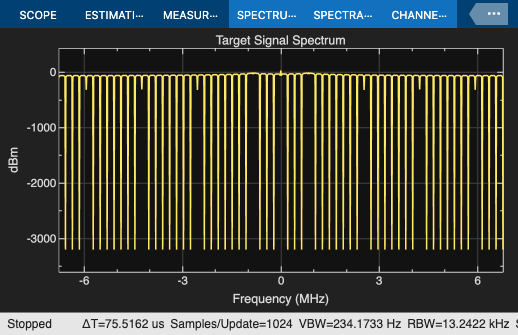

				Target transmitted full UID
			Initiator received CL1 UID without collision
				Complete UID received: 0x11aa22bb
				Initiator transmitted SELECT command
			Target received Cascade Level-1 SEL code
				Target selection confirmed
				Target transmitted SAK with UID complete flag
			Initiator received SAK
				UID complete. Exit Anticollision loop.
	End of Anticollision loop

	Target compliant with NFCIP-1. Continue with Transport Protocol Activation



nfcAnticollisionLoop(initiator, target, snrdB);


nfcProtocolActivation(initiator, target, snrdB);


	Start of Transport Protocol Activation
		Initiator transmitted ATR_REQ
		Target received ATR_REQ
			Target transmitted ATR_RES in response to ATR_REQ
		Initiator received ATR_RES
			Initiator transmitted PSL_REQ in response to ATR_REQ
			Selected send rate: 106 Kbps
			Selected receive rate: 106 Kbps
		Target received PSL_REQ
			Target transmitted PSL_RES in response to PSL_REQ
		Initiator received PSL_RES
			PSL_RES validated. All selected rates confirmed
	End of Transport Protocol Activation



nfcDataExchangeProtocol(initiator, target, snrdB);


	Start of Data Exchange Protocol (DEP)
		Initiator transmitted an Information PDU in DEP_REQ
			Initiator PNI: 0
		Target received an Information PDU in DEP_REQ
			MI chaining not activated in received information PDU
			Received Initiator PNI: 0
			Target PNI: 0
			Target transmitted an Information PDU in DEP_RES in response to DEP_REQ
		Initiator received an Information PDU in DEP_RES
			Received Target PNI: 0
		All data transmitted from Initiator to Target. Exit DEP.
	End of Data Exchange Protocol (DEP)




nfcProtocolDeactivation(initiator, target, snrdB)


	Start of Transport Protocol Deactivation
		Initiator transmitted RLS_REQ
		Target received RLS_REQ
			Target transmitted RLS_RES in response to RLS_REQ
		Initiator received RLS_RES
			Target released
	End of Transport Protocol Deactivation



nfcPrint.End();



End of NFC Communication between Initiator and Target




nfcPrint.Message('The message received by Target from Initiator:');

The message received by Target from Initiator:


nfcPrint.Message(target.ReceivedUserData);

Hello, from MathWorks.


nfcPrint.NewLine;

% Restore RNG state 
rng(s);


function nfcInitialization(initiator, target, snrdB)
    % Initialization and anticollision
    % Reference: ISO/IEC 14443-3, section 6

    txREQA = transmitREQA(initiator);

    sigPower = sum(abs(txREQA(:)).^2)/numel(txREQA);  % Puterea în watti
    sigPower_dBm = 10*log10(sigPower/0.001);
    fprintf('Puterea semnalului transmis masurata: %.8f dBm\n', sigPower_dBm);
    

    [rxREQA, noisevar] = awgn(txREQA, snrdB, 'measured');
    sigPowerRX = sum(abs(rxREQA(:)).^2)/numel(rxREQA);  % Puterea în watti
    sigPowerRX_dBm = 10*log10(sigPowerRX/0.001);
    fprintf('Puterea semnalului receptionat masurata: %.8f dBm\n', sigPowerRX_dBm);
    fprintf('Puterea zgomotului receptionat masurata: %.8f dBm\n', 10*log10(noisevar/0.001));
    % plot(txREQA);
    % plot(rxREQA);
    disp("txREQA: "+txREQA');
    disp("rxREQA: "+rxREQA');

    txATQA = receiveREQA(target, rxREQA);
    rxATQA = awgn(txATQA, snrdB, 'measured');
    plot(txATQA);
    plot(rxATQA);
    disp("txATQA: "+txATQA');
    disp("rxATQA: "+rxATQA');

    [isATQAValid, isCollisionDetected, isTargetCompliant] = ...
        receiveATQA(initiator, rxATQA);

    coder.internal.errorIf(~isATQAValid, 'comm:NFC:InvalidATQA');
    coder.internal.errorIf(isCollisionDetected, 'comm:NFC:CollisionATQA');
    coder.internal.errorIf(~isTargetCompliant, 'comm:NFC:TargetNotCompliant');    
end

function nfcAnticollisionLoop(initiator, target, snrdB)
    % Anticollision Loop
    % Reference: ISO/IEC 14443-3, section 6
    
    nfcPrint.NewLine;
    nfcPrint.Heading1('Start of Anticollision loop');
    
    % Start anticollision loop
    cascadeLevel = 1;
    targetRxAC = [];
    nfcPrint.CascadeLevel(cascadeLevel);
    [initiatorTxAC, newCascadeLevel, uidComplete, isoCompliantTarget] = ...
        antiCollisionLoop(initiator, targetRxAC, cascadeLevel);
    
    while (newCascadeLevel <= 3) && ~uidComplete
        
        nfcPrint.CascadeLevel(newCascadeLevel, cascadeLevel);
        cascadeLevel = newCascadeLevel;
        
        targetRxAC = awgn(initiatorTxAC, snrdB, 'measured');
        % Target's anticollision loop
        targetTxAC = antiCollisionLoop(target, targetRxAC);
        initiatorRxAC = awgn(targetTxAC, snrdB, 'measured');
        % Initiator's anticollision loop
        [initiatorTxAC, newCascadeLevel, uidComplete, isoCompliantTarget] = ...
            antiCollisionLoop(initiator, initiatorRxAC, cascadeLevel);
    end
    
    coder.internal.errorIf(~uidComplete, 'comm:NFC:IncompleteUID');
    coder.internal.errorIf(~isoCompliantTarget, ...
        'comm:NFC:TargetNotCompliantWithNFCIP1');
    
    nfcPrint.Heading1('End of Anticollision loop');
    nfcPrint.NewLine;    
    nfcPrint.Heading1(['Target compliant with NFCIP-1. '...
        'Continue with Transport Protocol Activation']);    
end

function nfcProtocolActivation(initiator, target, snrdB)
    % NFCIP-1 Transport Protocol Activation
    % Reference: ISO/IEC 18092, section 12.5
    
    nfcPrint.NewLine;
    nfcPrint.Heading1('Start of Transport Protocol Activation');
    
    txATR_REQ = transmitATR_REQ(initiator);
    rxATR_REQ = awgn(txATR_REQ, snrdB, 'measured');
    
    txATR_RES = receiveATR_REQ(target, rxATR_REQ);
    rxATR_RES = awgn(txATR_RES, snrdB, 'measured');
    
    txPSL_REQ = receiveATR_RES(initiator, rxATR_RES);
    rxPSL_REQ = awgn(txPSL_REQ, snrdB, 'measured');
    txPSL_RES = receivePSL_REQ(target, rxPSL_REQ);
    
    status = receivePSL_RES(initiator, txPSL_RES);
    coder.internal.errorIf(~status, 'comm:NFC:TPActivationFailed');
    
    nfcPrint.Heading1('End of Transport Protocol Activation');    
end

function nfcDataExchangeProtocol(initiator, target, snrdB)
    % Data Exchange Protocol
    % Reference: ISO/IEC 18092, section 12.6
    
    nfcPrint.NewLine;
    nfcPrint.Heading1('Start of Data Exchange Protocol (DEP)');
    
    status = nfcDEP(initiator, target, snrdB);
    coder.internal.errorIf(~status, 'nfc:NFC:DEPFailed');
    
    nfcPrint.Heading1('End of Data Exchange Protocol (DEP)');
    nfcPrint.NewLine;    
end

function nfcProtocolDeactivation(initiator, target, snrdB)
    % Transport Protocol Deactivation
    % Reference: ISO/IEC 18092, section 12.7

    nfcPrint.NewLine;
    nfcPrint.Heading1('Start of Transport Protocol Deactivation');

    txRLS_REQ = transmitRLS_REQ(initiator);
    rxRLS_REQ = awgn(txRLS_REQ, snrdB, 'measured');
    
    txRLS_RES = receiveRLS_REQ(target, rxRLS_REQ);
    rxRLS_RES = awgn(txRLS_RES, snrdB, 'measured');
    
    status = receiveRLS_RES(initiator, rxRLS_RES);
    coder.internal.errorIf(~status, 'comm:NFC:TPDeactivationFailed');
    
    nfcPrint.Heading1('End of Transport Protocol Deactivation');
end

## Exploration

Explore various methods of nfcInitiator and nfcTarget objects to understand various commands and protocols described by NFC standards. Experiment with various system parameters like SNR, UID type (Single or Double), UID value, SamplesPerSymbol to see how they impact the system.

## References

- [https://nfc-forum.org/](https://nfc-forum.org/)

- ISO/IEC 14443-2 Identification cards - Contactless integrated circuit cards - Proximity cards - Part 2: Radio frequency power and signal interface

- ISO/IEC 14443-3 Identification cards - Contactless integrated circuit cards - Proximity cards - Part 3: Initialization and anticollision

- ISO/IEC 18092 Information technology - Telecommunications and information exchange between systems - Near Field Communication - Interface and Protocol (NFCIP-1)

*Copyright 2016-2018 The MathWorks, Inc.*